clear all; close all
load('C:\Users\alexd\Downloads\200708_slice1.mat')
fs = 25000;
spikeMatrix = full(Spikes);

no channels variable cannot ground elec


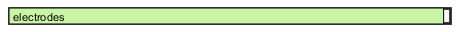

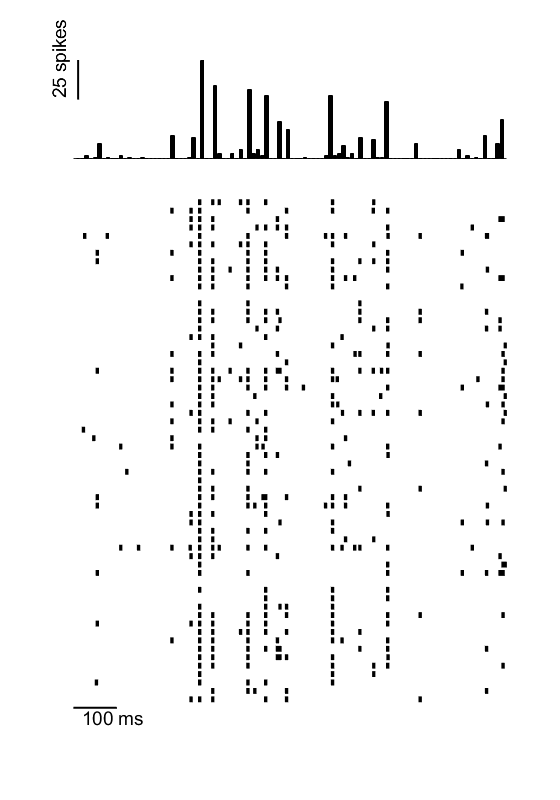

raster_1s_fcn(spikeMatrix,fs)

s = spikeMatrix(1:fs,:); % first 1 s of rec
s_vec = sum(s,2);
% get time point with the most spikes
num_chans = max(s_vec)

num_chans = 53

t = find(s_vec == max(s_vec))

t = 7289

% plot grid trace of this spike (1 ms before and after)
load('channels')
downFactor = 1;
% load dat
load('200708_slice1_1.mat');

% Filter signal
lowpass = 600;
highpass = 8000;
wn = [lowpass highpass] / (fs / 2);
filterOrder = 3; %changed from 3 to 5 by AD; and back
[b, a] = butter(filterOrder, wn);
filteredData = filtfilt(b, a, double(dat));

Unrecognized function or variable 'data'.


trace = filteredData(t-25:t+24,:);
MEAgraphics(1)
gridTrace_AD(trace, downFactor,'id',channels,fs)